# 1. Describe Raw Data

clear
clc

% Select folder where the data is
%savedir = uigetdir;
%cd(savedir)

% Delete the first file
delete("Raw_1001.mat");

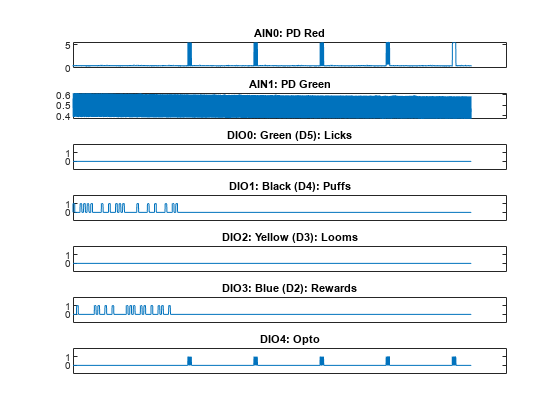


% load the raw data into a variable called output
D=dir('Raw_*.mat');
filename={D.name};
output=zeros(1,(length(filename)*(26000))); % this number needs to be the length of aData

for i=1:length(D)
    load(filename{i});
    output(((i-1)*(26000)+1):(i*(26000)))=temp;
end

%Create a handle to output for each channel
totalLen = length(output);
numChannels=13;
Ch1=find(mod(1:totalLen,numChannels)==1);   % Ch1: photodetector green
Ch2=find(mod(1:totalLen,numChannels)==2);   % Ch2: photodetector red
Ch3=find(mod(1:totalLen,numChannels)==3);   % Ch3: DAC0 167Hz Mod Copy (green)
Ch4=find(mod(1:totalLen,numChannels)==4);   % Ch4: DAC1 223Hz Mod Copy (red)
Ch5=find(mod(1:totalLen,numChannels)==5);   % Ch5: Green Licks
Ch6=find(mod(1:totalLen,numChannels)==6);   % Ch6: Black Puff
Ch7=find(mod(1:totalLen,numChannels)==7);   % Ch7: Yellow Loom
Ch8=find(mod(1:totalLen,numChannels)==8);   % Ch8: Blue Reward
Ch9=find(mod(1:totalLen,numChannels)==9);   % Opto

%Assign raw data for each channel of interest to named variables
raw_PD_green        =output(Ch1);
raw_PD_red          =output(Ch2);
Mod_green           =output(Ch3);
Mod_red             =output(Ch4);
align_green         =output(Ch5);
align_black         =output(Ch6);
align_yellow        =output(Ch7);
align_blue          =output(Ch8);
align_opto          =output(Ch9);

%Plot each channel of interest
figure;
ax = [];
ax(1) = subplot(7,1,1);plot(raw_PD_red);title('AIN0: PD Red');xticks([]);
ax(2) = subplot(7,1,2);plot(raw_PD_green);title('AIN1: PD Green');xticks([]);
ax(2) = subplot(7,1,3);plot(align_green);title('DIO0: Green (D5): Licks');yticks([0 1]);xticks([]);ylim([-1 2]);
ax(4) = subplot(7,1,4);plot(align_black);title('DIO1: Black (D4): Puffs');yticks([0 1]);xticks([]);ylim([-1 2]);
ax(5) = subplot(7,1,5);plot(align_yellow);title('DIO2: Yellow (D3): Looms');yticks([0 1]);xticks([]);ylim([-1 2]);
ax(6) = subplot(7,1,6);plot(align_blue);title('DIO3: Blue (D2): Rewards');yticks([0 1]);xticks([]);ylim([-1 2]);
ax(7) = subplot(7,1,7);plot(align_opto);title('DIO4: Opto');yticks([0 1]);xticks([]);ylim([-1 2]);
linkaxes(ax,'x');

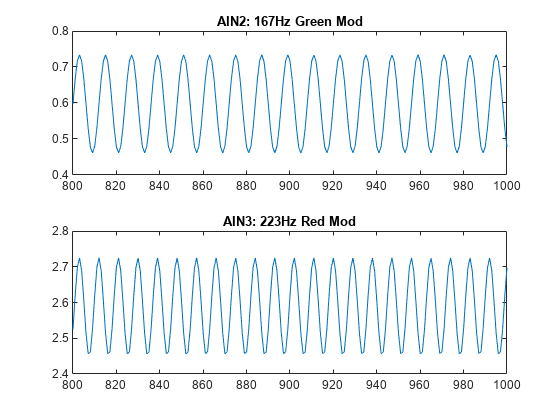

figure;
ax = [];
ax(1) = subplot(2,1,1);plot(Mod_green);title('AIN2: 167Hz Green Mod');xlim([800 1000]);ylim([0.4 0.8]);
ax(2) = subplot(2,1,2);plot(Mod_red);title('AIN3: 223Hz Red Mod');xlim([800 1000]);ylim([2.4 2.8])
linkaxes(ax,'x');

%cd("C:\Users\walla\Desktop\Davis_Fiber Photometry");

#### Demodulate Photodetector Signals

Set min and max values for params.freqRange1 and params.freqRange2 so each range spans the target oscillation frequency of that channel, and (ideally) excludes the oscillation on the opposite channel

% Creates a params struct
params.freqStep   = 5;          % Step size in Hz for freqency calculations
params.freqRange1 = [125 200];  % Min and max frequency range for channel 1 (target 167 Hz) (ex 125-200)
params.freqRange2 = [190 275];  % Min and max frequency range for channel 2 (target 223 Hz) (ex 200-275)
params.winSize = 0.04;          % Target window size (in sec) for FFT frequency calc (80 samples)
params.spectSample = 0.01;      % Step size for spectrogram (sec)
params.inclFreqWin = 4;         % Number of frequency bins to average (on either side of peak freq)
params.filtCut = 100;           % Cut off frequency for low pass filter of processed data
params.filtCutOsc = 500;        % Cut-off frequency for low-pass filter of oscillation data.
params.dsRate = 0.05;           % Time steps for down-sampling (seconds) (average of every 100 samples)

% Calculate Spectrograms for Channel 1 and 2
useFreqRange1 = params.freqRange1(1):params.freqStep:params.freqRange1(2);
[filtTimes, filtSig1, rawSig1, spectFreqs1, spectAmpVals1] = sfoReadFibPhot(raw_PD_green, 2000, useFreqRange1, params);

Spectrum window 0.064 sec; 128 samples at 2000 Hz



useFreqRange2 = params.freqRange2(1):params.freqStep:params.freqRange2(2);
[filtTimes, filtSig2, rawSig2, spectFreqs2, spectAmpVals2] = sfoReadFibPhot(raw_PD_red, 2000, useFreqRange2, params);

Spectrum window 0.064 sec; 128 samples at 2000 Hz



% Determine downsampled time points in output data set
dsTimes = filtTimes(1):params.dsRate:filtTimes(end); 

%__________________________Photobleaching Correction

% Fit: Fit each channel to exponential decay for photobleaching correction
pbFit1 = fit(filtTimes',filtSig1','exp2'); 
pbFit2 = fit(filtTimes',filtSig2','exp2');

% Correction: Divide filtered signal by exponential decay to correct for photobleaching
pbVals1 = (filtSig1' ./ double(pbFit1(filtTimes)))';
pbVals2 = (filtSig2' ./ double(pbFit2(filtTimes)))';

% Downsample photobleaching-corrected data
dsVals1 = interp1(filtTimes,pbVals1,dsTimes,'spline');
dsVals2 = interp1(filtTimes,pbVals2,dsTimes,'spline');

% Downsample raw (uncorrected) data
rawVals1 = interp1(filtTimes,filtSig1',dsTimes,'spline');
rawVals2 = interp1(filtTimes,filtSig2',dsTimes,'spline');


#### dF/F

Fs=20; 

g_0 = running_percentile(dsVals1, floor(Fs*10), 10);
g_dff = dsVals1'./g_0 - 1;
g_dff = g_dff';

r_0 = running_percentile(dsVals2, floor(Fs*10), 10);
r_dff = dsVals2'./r_0 - 1;
r_dff = r_dff';

#### Make Derivative Raw Trace

g_differ = diff(dsVals1');
r_differ = diff(dsVals2');
g_differ = g_differ';
r_differ = r_differ';
g_differ = [zeros(1, max(0, 1)), g_differ];
r_differ = [zeros(1, max(0, 1)), r_differ];

#### Z-score raw trace and diff

zscore_dsval1 = zscore(dsVals1);
zscore_dsval2 = zscore(dsVals2);
% 
zscore_g_diff = zscore(g_differ);
zscore_r_diff = zscore(r_differ);

The most useful output variables are:

-     filtTimes                            -- the time stamps of the raw output data

-     rawVals1 & rawVals2        -- output data before photobleaching correction    

-     dsTimes                            -- the time stamps of the downsampled output data

-     dsVals1 & dsVals2            -- photobleaching corrected data for channels 1 and 2

-     zscore_dsval1                   -- zscore of dsVals1

-     zscore_dsval2                   -- zscore of dsVals2

-     zscore_g_diff                     -- zscore of g_differ

-     zscore_r_diff                      -- zscore of r_differ

#### Plot 

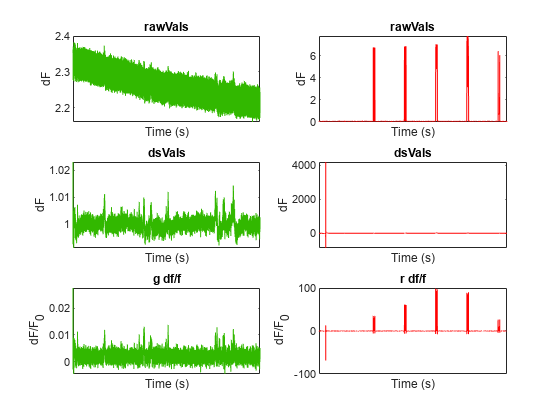

figure;
ax = [];

ax(1) = subplot(3,2,1);
plot(filtTimes,rawSig1, "Color", "#32B800"); title('rawVals');
xlabel('Time (s)')
ylabel(' dF ')
xticks([])
%ylim([0 2])

ax(2) = subplot(3,2,3);
plot(dsTimes,dsVals1, "Color", "#32B800"); title('dsVals');
xlabel('Time (s)')
ylabel(' dF ')
xticks([])
%ylim([0 2])

ax(3) = subplot(3,2,5);
plot(dsTimes,g_dff, "Color", "#32B800"); title('g df/f');
xlabel('Time (s)')
ylabel(' dF/F_0')
xticks([])
%ylim([-2 2])

ax(4) = subplot(3,2,2);
plot(filtTimes,rawSig2, "red"); title('rawVals');
xlabel('Time (s)')
ylabel(' dF ')
xticks([])
%ylim([0 2])

ax(5) = subplot(3,2,4);
plot(dsTimes,dsVals2, "red"); title('dsVals');
xlabel('Time (s)')
ylabel(' dF ')
%ylim([0 2])
xticks([])

ax(6) = subplot(3,2,6);
plot(dsTimes,r_dff, "red"); title('r df/f');
xlabel('Time (s)')
ylabel(' dF/F_0')
xticks([])
%ylim([-2 2])

linkaxes(ax, 'x');

% save('fibphotworkspace.mat')

# 4. Align to behavioral events

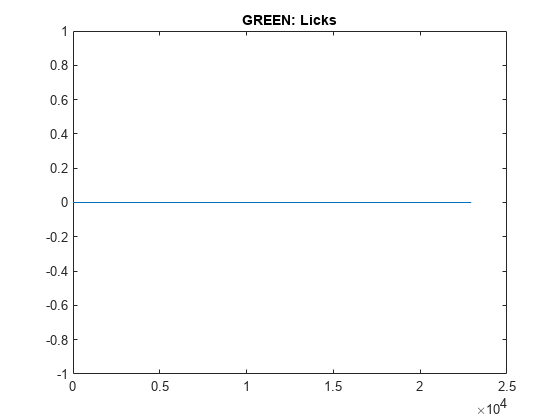

% clear
% load('fibphotworkspace.mat')

 

timetemp=linspace(0,length(Ch5)/2000,length(Ch5));

% _________________  Index to Align Green
ds_align_green = interp1(timetemp,align_green,dsTimes);
deriv_align_green = diff(ds_align_green);
align_green_onset_idx = find(deriv_align_green > 0);
align_green_offset_idx = find(deriv_align_green < 0);

figure;
plot(deriv_align_green);
title("GREEN: Licks")

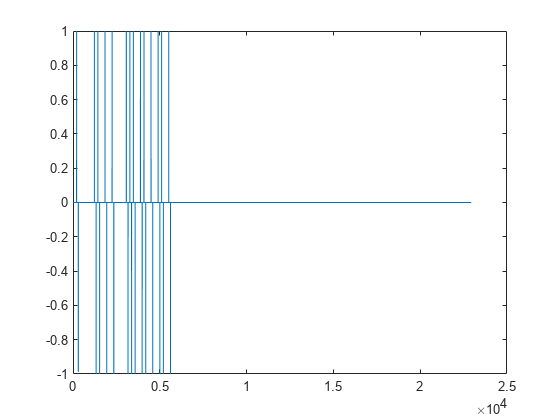


% _________________  Index to Align Blue
ds_align_blue = interp1(timetemp,align_blue,dsTimes);
deriv_align_blue = diff(ds_align_blue);
align_blue_onset_idx = find(deriv_align_blue > 0);
align_blue_offset_idx = find(deriv_align_blue < 0);

figure;
plot(deriv_align_blue);

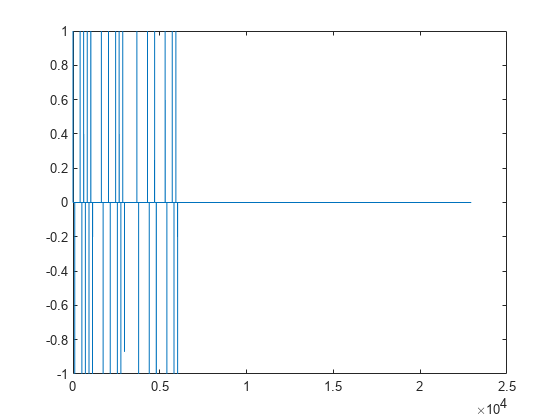


% _________________  Index to Align Black
ds_align_black = interp1(timetemp,align_black,dsTimes);
deriv_align_black = diff(ds_align_black);
align_black_onset_idx = find(deriv_align_black > 0);
align_black_offset_idx = find(deriv_align_black < 0);

figure;
plot(deriv_align_black);

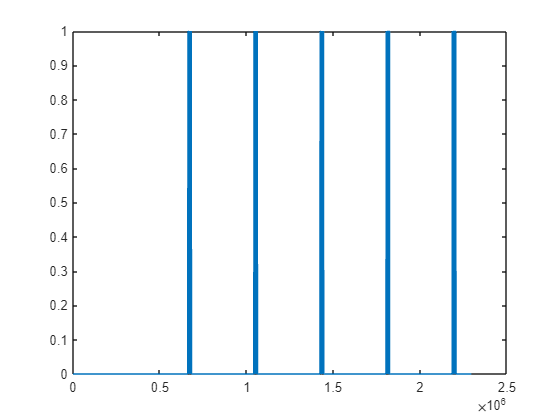


% % _________________  Index to Align Yellow
% ds_align_yellow = interp1(timetemp,align_yellow,dsTimes);
% deriv_align_yellow = diff(ds_align_yellow);
% align_yellow_onset_idx = find(deriv_align_yellow > 0);
% align_yellow_offset_idx = find(deriv_align_yellow < 0);
% 
% figure;
% plot(deriv_align_yellow);
% index = ismember(align_yellow_offset_idx, align_blue_offset_idx);
% index_to_delete = ~index;
% align_black_offset_idx = align_yellow_offset_idx(index_to_delete);

plot(align_opto);

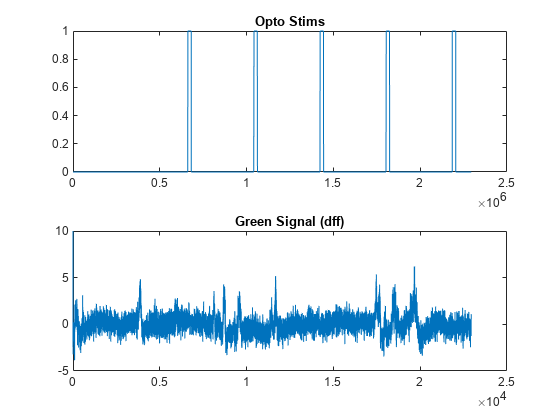

peaks = find(align_opto == 1);
peak_indices = [0, find(diff(peaks) > 1000), length(peaks)];
aligned_trains = zeros(size(align_opto));

for i = 1:length(peak_indices) - 1
    start_index = peaks(peak_indices(i) + 1);  % Start of pulse train
    end_index = peaks(peak_indices(i + 1));    % End of pulse train
    aligned_trains(start_index:end_index) = 1;
end

figure;
subplot(2,1,1);
plot(aligned_trains);
title("Opto Stims");
subplot(2,1,2);
plot(zscore_dsval1);
title("Green Signal (dff)");


ds_align_opto = interp1(timetemp,aligned_trains,dsTimes);
deriv_align_opto = diff(ds_align_opto);
align_opto_onset_idx = find(deriv_align_opto > 0);


% align_yellow_onset_idx = find(deriv_align_yellow > 0);
% align_yellow_offset_idx = find(deriv_align_yellow < 0);
% 
% figure;
% plot(deriv_align_yellow);
% title("YELLOW: Cue")


cd("C:\Users\walla\Desktop\Treadmill");

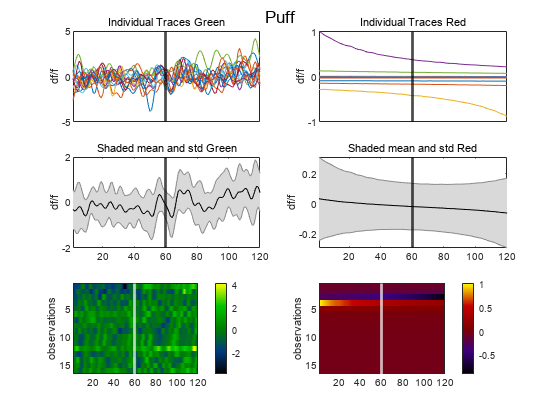

 

load('colormap_green_v2.mat')
load('colormap_red_v2.mat')

colormap_green_v2 = colormap_green_v2 / 255;
colormap_green_v2 = flipud(colormap_green_v2);
colormap_red_v2 = colormap_red_v2 / 255;
colormap_red_v2 = flipud(colormap_red_v2);

align_to(zscore_dsval1, zscore_dsval2, align_black_offset_idx, 3, "Puff", colormap_green_v2, colormap_red_v2)

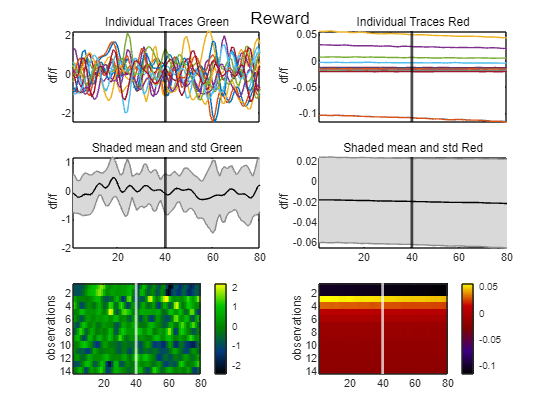

align_to(zscore_dsval1, zscore_dsval2, align_blue_offset_idx, 2, "Reward", colormap_green_v2, colormap_red_v2)

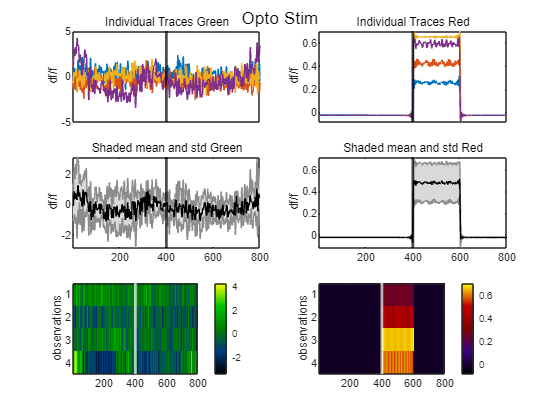

align_to(zscore_dsval1, zscore_dsval2, align_opto_onset_idx, 20, "Opto Stim", colormap_green_v2, colormap_red_v2)

%align_to(zscore_dsval1, zscore_dsval2, align_black_offset_idx, 2, "Puff Delivery")
%align_to(zscore_dsval1, zscore_dsval2, align_yellow_onset_idx, 1, "Cue")
%align_to(zscore_dsval1, zscore_dsval2, align_yellow_offset_idx, 2, "Cue off/Loom Off")
%align_to(zscore_dsval1, zscore_dsval2, align_green_offset_idx, 1, "Licks");

function align_to(green_signal, red_signal, alignment_indices, sec_around, title, colormap_green, colormap_red)    

    % Calculate trigger averages and individual traces for green signal
    [greenTrigAverage, greenTrigIndiv] = trigAvg(...
        green_signal, ...                  
        alignment_indices, ...         
        sec_around, ...
        sec_around, ...                              
        20 ...                              
    );

    % Initialize figure and axes array
    figure;
    ax = []; 
    
    % Prepare data for shadedErrorBar
    x = [];  % This could be the x-axis values if needed
    y_green = greenTrigIndiv';
    
    % Plot individual traces for green signal
    ax(1) = subplot(3, 2, 1);
    axes(ax(1));  % Set focus to subplot 1
    plot(greenTrigIndiv);
    xlim([1, sec_around * 40]);
    xline(sec_around * 20, "LineWidth", 2, Color="black");
    xticks([]);
    ylabel("df/f");
    subtitle("Individual Traces Green");
    
    % Plot shaded mean and standard deviation for green signal
    ax(2) = subplot(3, 2, 3);
    axes(ax(2));  % Set focus to subplot 3
    plot(greenTrigAverage);
    hold on;
    shadedErrorBar(x, mean(y_green, 1), std(y_green));
    hold off;
    xlim([1, sec_around * 40]);
    xline(sec_around * 20, "LineWidth", 2, Color="black");
    ylabel("df/f");
    subtitle("Shaded mean and std Green");

    % Display green signal as a heatmap (imagesc)
    ax(3) = subplot(3, 2, 5);
    axes(ax(3));  % Set focus to subplot 5
    imagesc(greenTrigIndiv');
    ylabel("observations");
    colorbar(ax(3));
    colormap(ax(3), colormap_green);
    xlim([1, sec_around * 40]);
    xline(sec_around * 20, "LineWidth", 2, Color="white");
    
    % ___________ Red Signal Processing ___________

    % Calculate trigger averages and individual traces for red signal
    [redTrigAverage, redTrigIndiv] = trigAvg(...
        red_signal, ...                  
        alignment_indices, ...      
        sec_around, ...
        sec_around, ...                              
        20 ...  
    );

    % Prepare data for shadedErrorBar
    y_red = redTrigIndiv';
    
    % Plot individual traces for red signal
    ax(4) = subplot(3, 2, 2);
    axes(ax(4));  % Set focus to subplot 2
    plot(redTrigIndiv);
    xlim([1, sec_around * 40]);
    xline(sec_around * 20, "LineWidth", 2, Color="black");
    xticks([]);
    ylabel("df/f");
    subtitle("Individual Traces Red");
    
    % Plot shaded mean and standard deviation for red signal
    ax(5) = subplot(3, 2, 4);
    axes(ax(5));  % Set focus to subplot 4
    plot(redTrigAverage);
    hold on;
    shadedErrorBar(x, mean(y_red, 1), std(y_red));
    hold off;
    xlim([1, sec_around * 40]);
    xline(sec_around * 20, "LineWidth", 2, Color="black");
    ylabel("df/f");
    subtitle("Shaded mean and std Red");

    % Display red signal as a heatmap (imagesc)
    ax(6) = subplot(3, 2, 6);
    axes(ax(6));  % Set focus to subplot 6
    imagesc(redTrigIndiv');
    ylabel("observations");
    colorbar(ax(6));
    colormap(ax(6), colormap_red);
    xlim([1, sec_around * 40]);
    xline(sec_around * 20, "LineWidth", 2, Color="white");

    % Add overall title to the figure
    sgtitle(title);
end
